### Extracting the SAM-recognized trees

By loading the output labeled matrix from the SAM classification and using it as a mask for the original hyperspectral image

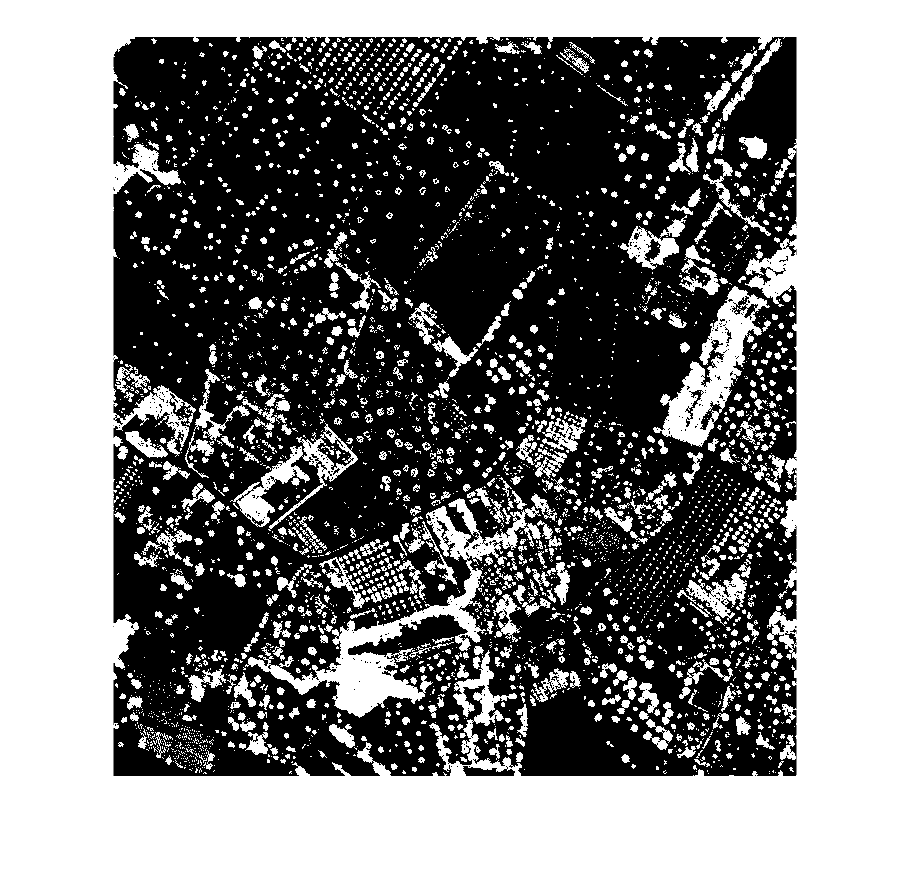

load("testGT.mat")
load("wavelengths.mat")
hcube = hypercube("CROP1_47.tiff",wavelength);
[rows, cols, ~] = size(hcube.DataCube);
% Masquerade taking all the pixels with label 2 (=Tree)
tree_mask = reshape(classMap==2, [rows, cols]);
figure
imshow(tree_mask,[])

sCube=size(hcube.DataCube);
tree_points=reshape(hcube.DataCube,[],sCube(3));
tree_points(~tree_mask,:)=0;
tree_points=reshape(tree_points,sCube);

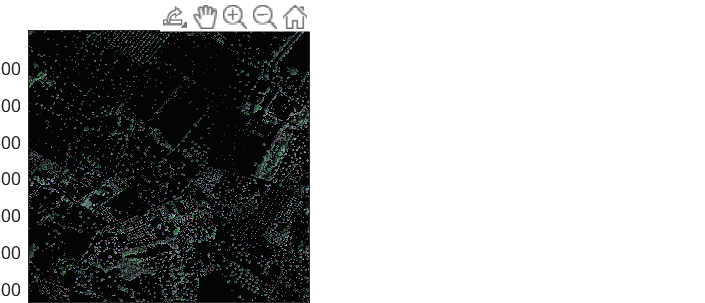

newhcube=hypercube(tree_points,wavelength);
fig = figure('Position',[0 0 700 300]);
axes1 = axes('Parent',fig,'Position',[0.04 0 0.4 0.9]);
rgbImg= colorize(newhcube,"Method","rgb","ContrastStretching",true);
imagesc(rgbImg,'Parent',axes1);

seg_crop=imread("Seg_Crop1.tif");
diff_trees=seg_crop-tree_mask;

diff_trees = 1480×1368 single matrix
    -1    -1    -1    -1    -1    -1    -1    -1    -1     0    -1     0     0    -1     0     0     0     0    -1    -1    -1     0    -1     0     0    -1    -1     0     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    -1    -1    -1    -1    -1    -1    -1    -1     0     0    -1     0     0    -1     0     0     0     0    -1     0     0    -1    -1    -1     0     0    -1    -1     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0     1     0     0     0     0     0
    -1    -1    -1    -1    -1     0     0    -1     0     0     0     0    -1    -1     0     0     0     0    -1     0     0     0    -1    -1    -1     0     0    -1     0     0     0     0     0    -1    -1    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    -1    -1    -1     0    -1     0     0    -1     0     0

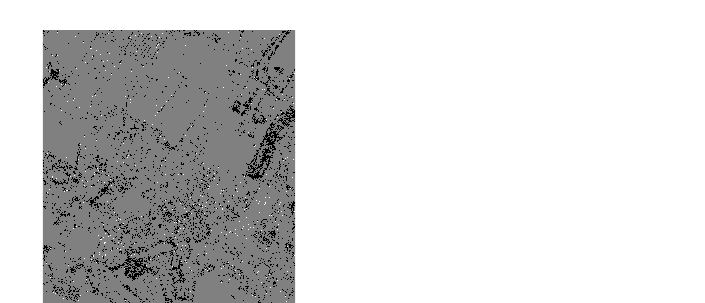

imshow(diff_trees,[])